# Copyright of this code belongs to Frank Lawless (flawless@uncc.edu).

Do not distribute this code.

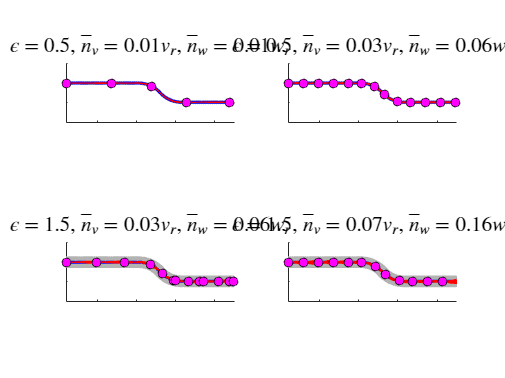

clear all
close all

% 'd' is the distance of the pen from the base of the robot
% 'k' is the control parameter
global d h k p epsilon;
% 'd' is the distance of the pen from the base of the robot
d = 2; 
epsilon = .5;  % desired tracking performance
k = 2;
h = .08; % step size
iterations = 20; % trials

% get lane-change reference trajectory
position = importdata("lane_change.mat");

T = size(position,2)-1;
t = 1:T;

xVelocity = (position(1,t+1) - position(1,t))/h;
yVelocity = (position(2,t+1) - position(2,t))/h;
% noise magnitudes
angular_noise = .01; % max 1
linear_noise = .01; % max 1

figure
for l = 1:4 % loop levels
    yb = [];xb = [];linear_vel = [];angular_vel = [];
    n1 = [];n2 = [];n1_max = [];n2_max = [];
    v = [];w = [];
    error_norm_max = [];error_norm = [];
    theta = [];theta_hat = [];
    for jj = 1:iterations % loop trials
        n1=[]; n2=[];
        p = 0; % adjust velocities/convergence time/communications

        % Initialize position
        theta_int = 0;
        state(:,1) =[position(1,1)-d*cos(theta_int)-.002; position(2,1)-d*sin(theta_int); theta_int];
        xb(1) = state(1,1) + d*cos(state(3,1));
        yb(1) = state(2,1) + d*sin(state(3,1));
        
        xba(jj,1) = xb(1);
        yba(jj,1) = yb(1);
        
        theta(1) = state(3,1);
        theta_hat(1) = state(3,1);
        thetatk = theta(1);
        thetaa = theta(1);
        T = size(position,2)-1;
        t = 1:T;
        
        % Get reference velocities
        xVelocity = (position(1,t+1) - position(1,t))/h;
        yVelocity = (position(2,t+1) - position(2,t))/h;
        
        % Calculated maximum reference velocities
        vr = max(sqrt(xVelocity.^2+yVelocity.^2));
        wr = vr/d;
        
        % Bound noise
        nv = linear_noise*vr;
        nw = angular_noise*vr/d;
        eta1 = sqrt(nv^2+d^2*nw^2);
        
        % Initial error
        e(:,1) = [position(1,1)-xb(1); position(2,1)-yb(1)];
        e_tk = e(:,1);
        
        tk = 0;
        o1 = eta1/vr*(1+eta1/(nw*norm(e(:,1))));
        o2 = eta1^2/(vr*nw*norm(e(:,1)));
        
        pk = (-o1+sqrt(o1^2+4*o2))/2 +p; % p is used to slightly adjust pk
        
        
        tf = tk + pk*norm(e_tk)/eta1;
        
        % Initial equation 3.15
        b1 = norm(e_tk)/(tf-tk)-eta1;
        b2 = (vr+norm(e_tk)/(tf-tk))*nw/2;
        
        tk1 = tk+b1/(2*b2);
        
        CT = eta1^2*(1-pk)^2/(2*nw*(vr*pk^2+eta1*pk));
        N = ceil((norm(e(:,1))-epsilon)/CT);
        
        actual_error(:,1) = e(:,1);
        error_history(1) = norm(e(:,1));
        w_history = [];
        i = 0; k = 1; first = true; trigger_time = 1; trigger = false;

        for t = [0 : 1 : T-1]*h %Trigger t = tk1
            i = i+1;
        
            if t <= tf
                e_th(i) = norm(e_tk) - b1*(t-tk) + b2*(t-tk)^2;
            else
                e_th(i) = eta1*(t-tk) + b2*(t-tk)^2;
            end
        
        
            if t > tk1 -h
                w_history = [];
                trigger_time = 1;
                k = k+1;
                tk = t;
                e_tk = actual_error(:,i);
        
                o1 = eta1/vr*(1+eta1/(nw*norm(actual_error(:,i))));
                o2 = eta1^2/(vr*nw*norm(actual_error(:,i)));
        
                pk = (-o1+sqrt(o1^2+4*o2))/2 +p;
                if pk >= .99
                    pk = .99;
                end
                tf = tk + pk*norm(e_tk)/eta1;
                
                b1 = norm(e_tk)/(tf-tk)-eta1;
                b2 = (vr+norm(e_tk)/(tf-tk))*nw/2;
        
                if norm(e_tk) > epsilon && first == true
                    tk1 = tk+b1/(2*b2);
                else
                    first = false;
                    tk1 = tk + (b1+sqrt(b1^2-4*b2*(norm(e_tk)-epsilon)))/(2*b2);
                    if tk1 > tf 
                       tk1 = max(tk + (-eta1 + sqrt(eta1^2 + 4 * epsilon* b2) )/(2*b2), tf);
                       if tk + (-eta1 + sqrt(eta1^2 + 4 * epsilon* b2) )/(2*b2) < tf
                           keyboard
                       end
                    end
                end
                trigger = true;
            end

            if trigger == true % Save tk/e_th when there is a trigger
                trigger = false;
                    trigger_history(k) = tk;
                    error_history(k) = e_th(i);
                    trigger_position(:,k) = [xba(jj,i); yba(jj,i)];
               
                ref_position(:,k) = [position(1,i); position(2,i)];

                % estimates are updated
                xb(i) = xba(jj,i);
                yb(i) = yba(jj,i);
                theta(i) = thetaa(i);
        
            end
    
            x = [xb(i); yb(i); theta(i)];
        
            [v(i), w(i)] = controller(x, e_tk, t, tf, tk, xVelocity(i), yVelocity(i));
        
            n1(i) = (linear_noise-2*linear_noise*rand)*vr;
            n2(i) = (angular_noise-2*angular_noise*rand)*wr;
         
            linear_vel(i) = v(i)+n1(i);
            angular_vel(i) = w(i)+n2(i);
        
            % Propagate the estimated dynamics
            dot_x(:,i) = estimated_dynamics(theta(i),v(i),w(i));
            xb(i+1) = xb(i) + dot_x(1,i)*h;
            yb(i+1) = yb(i) + dot_x(2,i)*h;
            theta(i+1) = theta(i) + dot_x(3,i)*h;
        
            % Propagate the actual dynamics
            dota_x(:,i) = dynamics(thetaa(i),v(i),w(i),n1(i), n2(i));
            xba(jj,i+1) = xba(jj,i) + dota_x(1,i)*h;
            yba(jj,i+1) = yba(jj,i) + dota_x(2,i)*h;
            thetaa(i+1) = thetaa(i) + dota_x(3,i)*h;
    
            %save error and centroid
            e_estimated(:,i+1) = position(1:2,i+1) - [xb(i+1); yb(i+1)];
            actual_error(:,i+1) = position(1:2,i+1) - [xba(jj,i+1); yba(jj,i+1)];
            state(:,i+1) = [xba(jj,i+1)-d*cos(thetaa(i+1));yba(jj,i+1)-d*sin(thetaa(i+1));thetaa(i+1)];
        end

        for i = 1:length(trigger_history)
            trigger_x(i) = trigger_history(i);
            trigger_y(i) = [error_history(i)];
        end

        for i = 1:length(actual_error)
            error_norm(i) = norm(actual_error(:,i));
        end
    end
        
    % error 
    error_norm_max = 0;theta_e_max = 0;error_int = 0;
    n2_max = 0;n1_max = 0;theta_e = [];
    for j = 1:iterations
        for i = 1:length(position)
            error = [position(1,i) - xba(jj,i); position(2,i) - yba(jj,i)];
            error_norm(i) = norm(error);        
        end
        if j > 1 
            if max(error_norm(1)) > error_int
                error_int = max(error_norm(1));
            end
        else 
            error_int = max(error_norm(1));
            n2_max = max(angular_noise(j,:));
            n1_max = max(linear_noise(j,:));
            error_norm_max = max(error_norm(:));
        end
    end

    u = [];
    subplot(2,2,l);
    for i = 1:1:length(position)
        circle(position(1,i), position(2,i),epsilon,[.7 .7 .7],1);
    end
    hold on
    h1(1) = plot(position(1,:),position(2,:),'color','b','LineWidth',2,'DisplayName','reference trajectory'); 
    for j = 1:iterations
        h1(2) = plot(xba(j,:), yba(j,:),'color',[1 0 0],'DisplayName',sprintf('base-point for %d trails',iterations));
    end
    scatter(ref_position(1,:), ref_position(2,:),'filled','MarkerFaceColor','m', ...
        'MarkerEdgeColor','k');
    axis equal
    xlim([d 45])
    ylim([-10 5])
    title({['$\epsilon$ = ', num2str(epsilon), ', $\bar{n}_v = $', num2str(linear_noise),'$v_r$', ...
        ', $\bar{n}_w = $', num2str(angular_noise),'$w_r$']},'Interpreter','latex',fontsize=14)
    daspect([1 1 1])
    set(gca,'xticklabel',[])
    set(gca,'yticklabel',[])
    hold off
    
    % increase noise levels for level 2, 4 and epsilon for level 3
    if l == 1
        angular_noise = angular_noise + .05;
        linear_noise = linear_noise + .02;
    elseif l == 2
        epsilon = epsilon+1;
    elseif l == 3 
        angular_noise = angular_noise + .1;
        linear_noise = linear_noise + .04;
    end
end

function [v, w] = controller(x, e_tk, t, tf, tk, xVelocity, yVelocity)
global d
J = [cos(x(3)) -d*sin(x(3));
    sin(x(3))  d*cos(x(3)) ];

if t < tf
    u = e_tk/(tf-tk);
else
    u = 0;
end

v_feedback = [xVelocity; yVelocity] + u;

desired_control = (J)\v_feedback;

v = desired_control(1);
w = desired_control(2);

end


function dot_x = estimated_dynamics(theta,v,w)
global d

M = [cos(theta) -d*sin(theta);
    sin(theta)  d*cos(theta);
    0               1      ];

dot_x = M*[v; w];
end

function dot_x = dynamics(theta,v,w,n1,n2)
global d

M = [cos(theta) -d*sin(theta);
    sin(theta)  d*cos(theta);
    0               1      ];

dot_x = M*[v+n1; w+n2];
end


function circles = circle(x,y,r,c,trans)
hold on
th = 0:pi/50:2*pi;
x_circle = r * cos(th) + x;
y_circle = r * sin(th) + y;
fill(x_circle, y_circle,c,'LineStyle','none','FaceAlpha', trans,'HandleVisibility','off')
end